clear; close all;

X = readmatrix('Sample Geometry.xlsx');
X = X(:,2:end)

X =     2.0000         0         0
    1.0000    3.0000         0
         0         0         0
    2.0000         0    2.0000
    0.8000    2.8000    2.2000
         0         0    1.8000
         0         0         0
         0         0         0
         0         0         0
         0         0         0


[A, B, C, D, E, F, G, H, J, K, L, M, N, P, R] = deal(...
    X(1,:), X(2,:), X(3,:), X(4,:), X(5,:),...
    X(6,:), X(7,:), X(8,:), X(9,:), X(10,:),...
    X(11,:), X(12,:), X(13,:), X(14,:), X(15,:) ...
    )

A =      2     0     0


B =      1     3     0


C =      0     0     0


D =      2     0     2


E =     0.8000    2.8000    2.2000


F =          0         0    1.8000


G =      0     0     0


H =      0     0     0


J =      0     0     0


K =      0     0     0


L =      0     0     0


M =     1.5000    3.0000         0


N =     2.5000         0         0


P =      0     0     0


R =      0     0     0


Check points

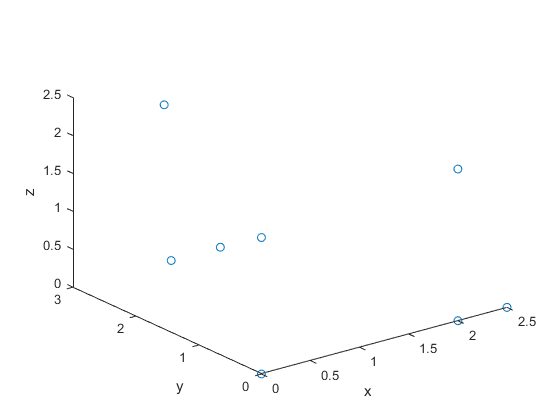

plot3(X(:,1), X(:,2), X(:,3), 'o')
xlabel('x')
ylabel('y')
zlabel('z')

Coordinates of B as a function of LCA angle

AC = C - A

AC =     -2     0     0


AB = B - A

AB =     -1     3     0


ABp = AC .* (dot(AB, AC)./norm(AC)^2)

ABp =     -1     0     0


Bp = A + ABp

Bp =      1     0     0


BpB = B - Bp

BpB =      0     3     0


Rotate LCA and UCA

Brot = rotate_A_arm(A, B, C, pi/6)

Brot =     1.0000    2.5981   -1.5000


Erot = rotate_A_arm(D, E, F, pi/6)

Erot =     0.9435    2.5841    0.7645


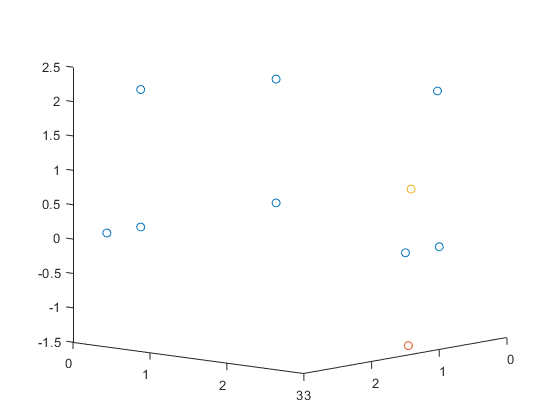

plot3(X(:,1), X(:,2), X(:,3), 'o', Brot(1), Brot(2), Brot(3), 'o',...
    Erot(1), Erot(2), Erot(3), 'o')

Check that magnitudes haven't changed

norm(AB) - norm(Brot - A)

ans = 4.4409e-16

norm(C - B) - norm(C - Brot)

ans = 4.4409e-16

norm(E - D) - norm(Erot - D)

ans = 0

norm(F - E) - norm(F - Erot)

ans = 0

Try to solve for UCA from LCA

alpha = pi/6

alpha = 0.5236


upright_length = norm(E - B)

upright_length = 2.2181

Brot = rotate_A_arm(A, B, C, alpha)

Brot =     1.0000    2.5981   -1.5000



beta = fzero(@(beta) norm(rotate_A_arm(D, E, F, beta) - Brot) - upright_length, alpha)

beta = 0.5421

Now rotate UCA by the suggested angle

Erot = rotate_A_arm(D, E, F, beta)

Erot =     0.9483    2.5629    0.7172



norm(E - B) - norm(Erot - Brot)

ans = 0

## Steering angle

Mrot = rotate_A_arm(B, M, E, pi/6)

Mrot =     1.4336    3.2485    0.0166


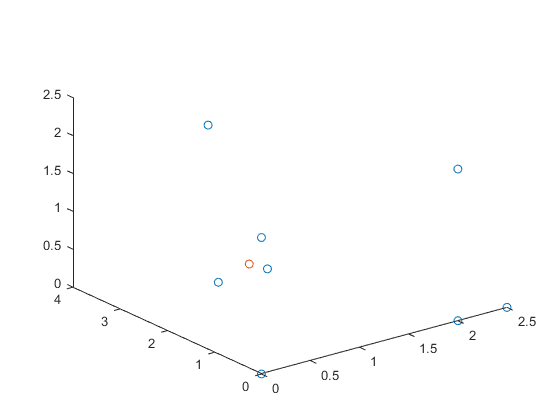

plot3(X(:,1), X(:,2), X(:,3), 'o', Mrot(1), Mrot(2), Mrot(3), 'o')